%EE 451 Lab 11
%Lisa Jacklin
%11/17/23

%note that in order to do the following we need to use the filters which
%you can find in lab slideset 11

%note that the following code is also in sideset 11 for labs
Wp = 0.2*pi; Ws = 0.3*pi; Rp = 7; As = 16;
[b, a] = afd_butt(Wp, Ws, Rp, As);


*** Butterworth Filter Order =  3


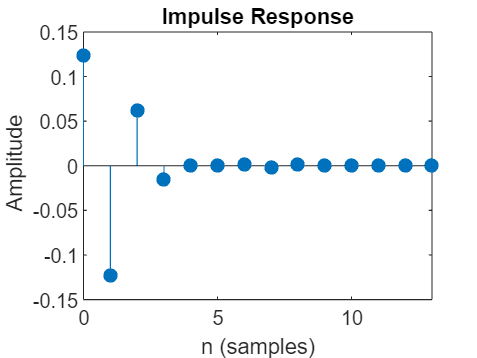


w = [0:1:500] * (0.5*pi)/500;
H = freqs(b,a,w);
mag = abs(H); db = 20*log10((mag)/max(mag));
pha = angle(H);
impz(b,a);

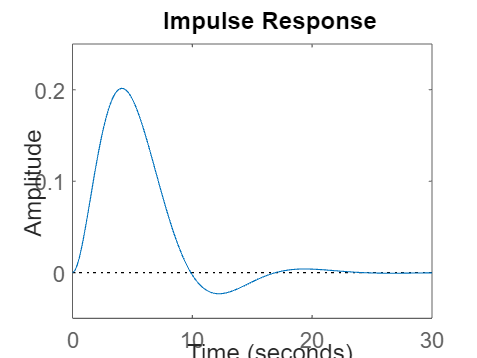

figure
impulse(b,a);

c = [ 1 1];
d = [ 1 5 6];
[R, p, k] = residue(c,d);

%finish me maybe...?
